## Treino para teste PL2

#### I. Sinais Compostos por Sinusoides 1. Determine o período, a frequência e o valor máximo (valor de pico) de cada um dos seguintes sinais periódicos. Verifique visualmente no MATLAB.

Ta = 0.01;
t = (0:Ta:5);

####  a) 𝑥(𝑡) = 2 sin(4𝜋𝑡)

T = 1/2;

f = 2;

A = 2;

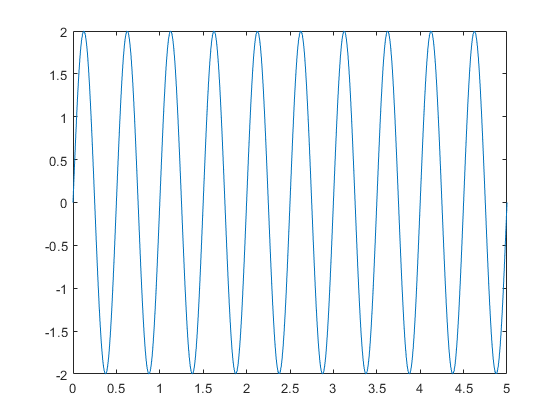

x = 2.*sin(4*pi.*t);
plot(t,x);

#### b) 𝑦(𝑡) = sin(10𝜋𝑡 + 𝜋/2) 

T = 1/5;

f = 5;

A = 1;

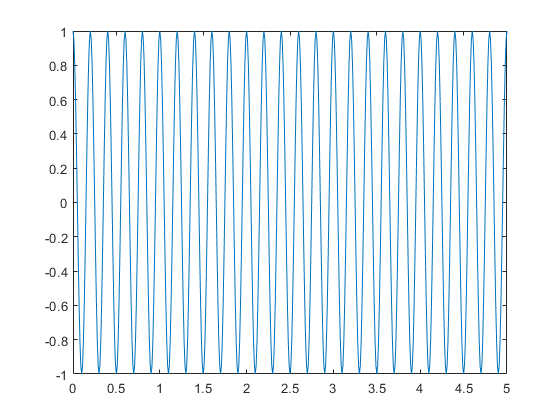

y = sin(10*pi.*t+pi/2);
plot(t,y);

#### c) 𝑧(𝑡) = sin(6𝜋𝑡) + sin(8𝜋𝑡) 

T = 1/2;

f = 1;

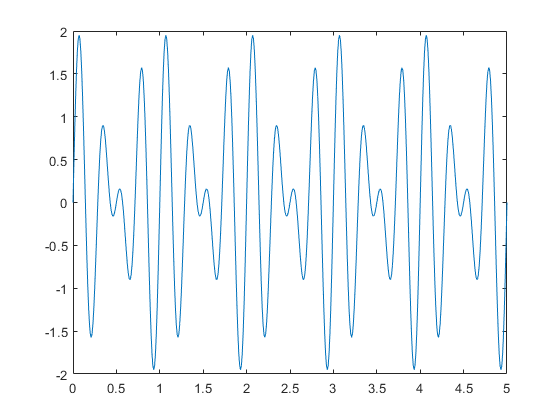

z = sin(6*pi.*t) + sin(8*pi.*t);
plot(t,z);

#### d) 𝑤(𝑡) = sin(6𝜋𝑡) + sin(8𝜋𝑡 + 0.1) 

T = 1/2;

f = 1;

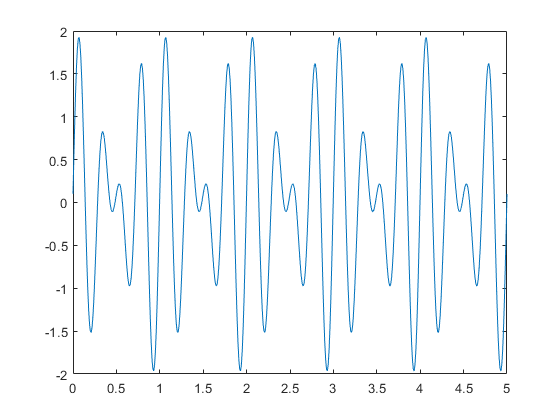

w = sin(6*pi.*t) + sin(8*pi.*t+0.1);
plot(t,w);

#### e) 𝑞(𝑡) = sin(6𝜋𝑡) + sin(7𝜋𝑡) + sin(8𝜋𝑡) 

T = 1;

f = 1;

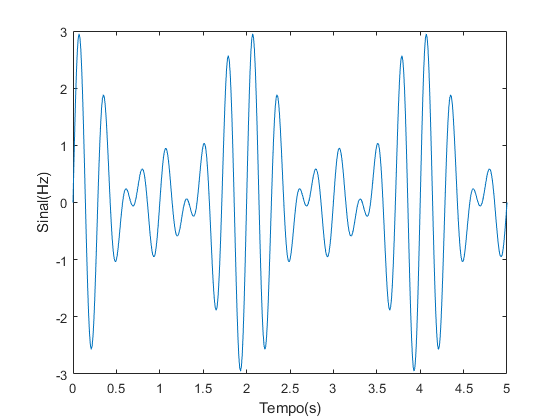

q = sin(6*pi.*t) + sin(7*pi.*t) + sin(8*pi.*t);
plot(t,q);
xlabel("Tempo(s)");
ylabel("Sinal(Hz)");

### 2. Com base no que verificou na alínea 1, obtenha a relação que determina o período de um sinal genérico descrito por: 

### 𝑥(𝑡) = ∑𝐴𝑛 sin(2𝜋𝑓𝑛𝑡 + 𝜙𝑛 ) 𝑁 𝑛=1 . 

A relação que determina o sinla genérico de x(t) é o 1/(máximo divisor comum das frequências fn a fN)

### 3. Determine a potência associada a cada um dos sinais representados na alínea 1. Desenvolva uma função no MATLAB que, aceitando como argumentos de entrada o vetor de amostras de um sinal, 𝑥, o período de amostragem referente a esse sinal, 𝑇𝑎, e o período do sinal, 𝑇, retorna a potência associada ao sinal.

potencia(x,Ta,1/2)

ans = 2.0000

### 4. Considere um conjunto de sinais definidos pela expressão da alínea 2, onde 𝑁 = 3, 𝐴1 = 𝐴2 = 𝐴3 = 1, e 𝑓1 = 1.1𝑓2 = 1.2𝑓3 = 3 𝑘𝐻𝑧. Testando diferentes valores para 𝜙𝑛, 𝑛 = 1,2,3, determinados aleatoriamente entre ] − 𝜋; 𝜋], mostre que as realizações obtidas para o sinal 𝑥(𝑡) são muito distintas entre si (e que o valor de pico varia notoriamente), mas que todas mantêm a mesma potência. Explique esta observação.

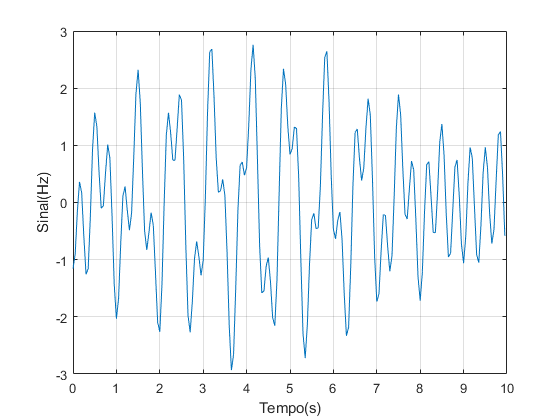

T = 1/100;
Ta  = 5 * T/1000;
t = (0:Ta:T-Ta/5);
f1 = 1100;
f2 = 1200;
f3 = 3000;
weirdn = 2*pi*(rand(1,3) + 0.0001) - pi;
x = sin(2*pi*f1.*t + weirdn(1)) + sin(2*pi*f2.*t + weirdn(2)) + sin(2*pi*f3.*t + weirdn(3));
plot(t,x);
xlabel("Tempo(s)");
ylabel("Sinal(Hz)");
grid;

power = potencia(x,Ta,T)

power = 1.5000